# Interpolation of Numerical Data

This section discusses the Linear Interpolation and Cubic Spline Interpolation along with multiple examples per method. 

## Interpolation Problem Statement

`Interpolation` is the process of `estimating unknown values` that fall between known values. It is widely used in engineering and science to `estimate values from discrete data points`. The `goal is to construct a function` that passes through or near these known points and can be used to estimate values at any intermediate points.

Interpolation can be thought of as "table lookup".

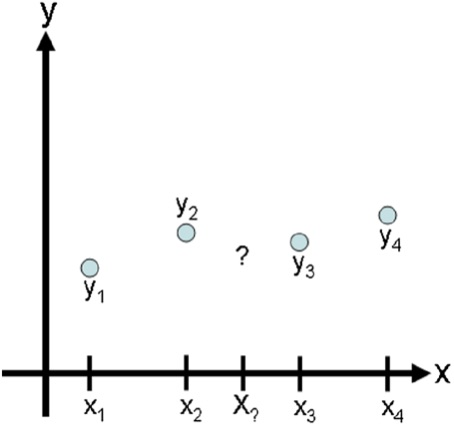

Let's start by defining a simple dataset of `x` and `y` values:

clear all; clc; close all;

% Example dataset
x = [1, 2, 3, 4, 5]; % uniform sampling, e.x. time-based
y = [2, 25, 20, 32, 40]; % noisy sensor measurements

% Plot the data points
figure;
plot(x, y, 'o', 'MarkerFaceColor', 'k', 'MarkerSize',10);
xlabel('x');
ylabel('y');
title('Data Points for Interpolation');
grid on;

This plot shows our known data points. We will now explore various interpolation methods to estimate values between these points.

## Linear Interpolation

Linear interpolation is the simplest form of interpolation. It assumes that the unknown value between two points lies on the straight line connecting the points. Here is the algorithm used by this method:


$$\hat y = y_i +\frac{y_{i+1}-y_i}{x_{i+1}-x_i}\cdot(x-x_i)$$


The most general interface to the function is here:

[`vq = interp1(x,v,xq,method,extrapolation)`](https://www.mathworks.com/help/matlab/ref/interp1.html#d126e845157)

### Example 1: Simple Linear Interpolation

% Query points
xq = 1.5;

% Linear interpolation
yq_lin = interp1(x, y, xq);

% plot
figure();
plot(x, y, 'o', 'MarkerFaceColor', 'k', 'MarkerSize',10);hold on
plot(xq, yq_lin, 'd', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
xlabel('x');
ylabel('y');
legend('Data Points', 'Interpolated Point');
grid on;hold off;

### Example 2: Linear Interpolation over Multiple Points

% Query points can be represented by a vector
xq = [1.5, 2.5, 3.5, 4.5];

% Linear interpolation is fully vectorized method
yq_mulp = interp1(x, y, xq);

% Plot
figure()
plot(x, y, 'o', 'MarkerFaceColor', 'k', 'MarkerSize',10);hold on
plot(xq, yq_mulp, 'd', 'MarkerFaceColor', 'r','MarkerSize', 10);
legend('Data Points', 'Interpolated Point');
xlabel('x');
ylabel('y');
grid on;hold off;

### Exercise

Experiment with the other `methods` available in the `interp` function

% 

## Cubic Spline Interpolation

Cubic [Spline](https://www.mathworks.com/help/matlab/ref/spline.html) interpolation creates a smooth curve by fitting cubic polynomials between each pair of data points.


$$S_i(x) = a_i\cdot x^3+b_i\cdot x^2+c_i\cdot x+d_i$$


The approach ensures that the curve is continuous and has continuous first and second derivatives. The interface to the function is:

[`s`](https://www.mathworks.com/help/matlab/ref/spline.html#bvjdpi3-s) `= spline(`[`x`](https://www.mathworks.com/help/matlab/ref/spline.html#bvjdpi3-x)`,`[`y`](https://www.mathworks.com/help/matlab/ref/spline.html#bvjdpi3-y)`,`[`xq`](https://www.mathworks.com/help/matlab/ref/spline.html#mw_ed3ec909-e931-41ce-a281-ba326a9c1b85)`)` returns a vector of interpolated values `s` corresponding to the query points in `xq`. The values of `s` are determined by cubic spline interpolation of `x` and `y`.

(You also can perform spline interpolation using the [`interp1`](https://www.mathworks.com/help/releases/R2024b/matlab/ref/double.interp1.html) function with the command `interp1(x,y,xq,'spline')`. While `spline` performs interpolation on rows of an input matrix, `interp1` performs interpolation on columns of an input matrix.)

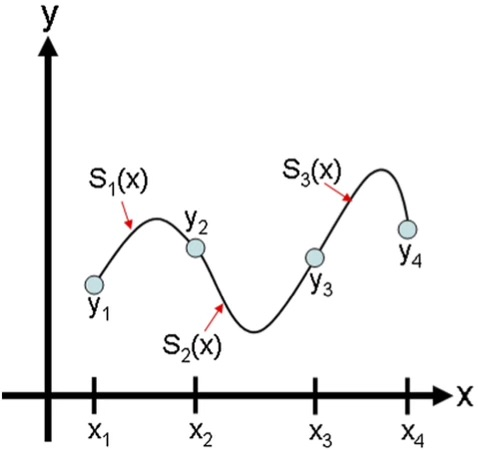

### Example 1: Basic Cubic Spline Interpolation

% Cubic Spline interpolation
yq = spline(x, y, xq);

% Plot
figure;
plot(x, y, 'o', 'MarkerFaceColor', 'k', 'MarkerSize',10);hold on
plot(xq, yq, 'ro', 'MarkerFaceColor','r')
xlabel('x');
ylabel('y');
title('Cubic Spline Interpolation');
legend('Data Points', 'Spline-Interpolated Curve', 'Location','northwest');
grid on;hold off;


### Example 2: Spline Interpolation with More Points

% A denser set of query points
xqq = linspace(1, 5, 100);

% Cubic Spline interpolation
yqq = spline(x, y, xqq);

% Plot
figure;
plot(x, y, 'o', 'MarkerFaceColor', 'k', 'MarkerSize',10);
hold on
plot(xqq, yqq, 'ro', 'MarkerFaceColor','r')
xlabel('x');
ylabel('y');
title('Dense Cubic Spline Interpolation');
legend('Data Points', 'Spline-Interpolated Curve' ,'Location','northwest');
grid on;hold off;


### Example 3: Spline vs Linear Interpolation

xq = linspace(1, 5, 25);
% Linear interpolation
yq_linear = interp1(x, y, xq);

% Cubic spline interpolation
yq_spline = spline(x, y, xq);

% Plot
figure;
plot(x, y, 'o', 'MarkerFaceColor', 'k', 'MarkerSize',10);hold on
plot(xq, yq_linear, 'o', 'MarkerFaceColor','r', 'MarkerSize',6)
plot(xq, yq_spline, 'o', 'MarkerFaceColor','b')
xlabel('x');
ylabel('y');
title('Cubic Spline vs Linear Interpolation');
legend('Data Points', 'Linear Interpolation', 'Cubic Spline Interpolation', 'Location','northwest');
grid on;hold off;


## Summary

This sectioned explored different interpolation methods available in MATLAB, including Linear Interpolation, Cubic Spline Interpolation, and Lagrange Polynomial Interpolation. Each method has its strengths and weaknesses:

- `Linear` Interpolation: Simple and efficient, but may not capture the true shape of the data.

- `Cubic Spline` Interpolation: Produces smooth curves that are more accurate for continuous data.